Семинар 3.

## **Тема:** "Решение переопределенной системы линейных алгебраических уравнений"

**Задание:** Сигнал f(x) измеряется в точках c погрешностью, не превышающей $\delta$. Аппроксимировать f(x) полиномом.

## Отчёт:

Фиксируем функцию f(x) = sin(x);

С ростом N число обусловленности и ошибка растут, однако очень медлено, ~o(N); С ростом M резко возрастает число обусловленности системы, уже при M > 9 $\mu \left(A\right)>{10}^3$. Изменения $\delta$ не оказывают влияния на обусловленность оператора, однако ошибка стремится к нулю вместе с $\delta$.

clc;
clear;
N = 260

N = 260

x = -1:2/N:1;
d_x = 0.00001

d_x = 1.0000e-05

disturbance = -d_x + 2*d_x*rand(size(x));
fd_x = sin(x) + disturbance

fd_x =    -0.8415   -0.8373   -0.8331   -0.8288   -0.8244   -0.8201   -0.8156   -0.8112   -0.8067   -0.8021   -0.7975   -0.7928   -0.7881   -0.7833   -0.7785   -0.7737   -0.7688   -0.7638   -0.7588   -0.7538   -0.7487   -0.7436   -0.7385   -0.7332   -0.7280   -0.7227   -0.7173   -0.7120   -0.7066   -0.7011   -0.6956   -0.6900   -0.6844   -0.6788   -0.6732   -0.6674   -0.6617   -0.6559   -0.6501   -0.6442   -0.6383   -0.6324   -0.6264   -0.6204   -0.6143   -0.6082   -0.6021   -0.5960   -0.5898   -0.5835


M = 9

M = 9

system = [];
for i = 0:M
  column = (x.^i)';
  system = horzcat(system, column);
end;
p = system\fd_x'

p =     0.0000
    1.0000
    0.0000
   -0.1666
   -0.0001
    0.0080
    0.0001
    0.0003
   -0.0001
   -0.0003


mu_A = cond(system)

mu_A = 1.2717e+03

error = max(abs(sin(x)' - system * p))

error = 7.4648e-06

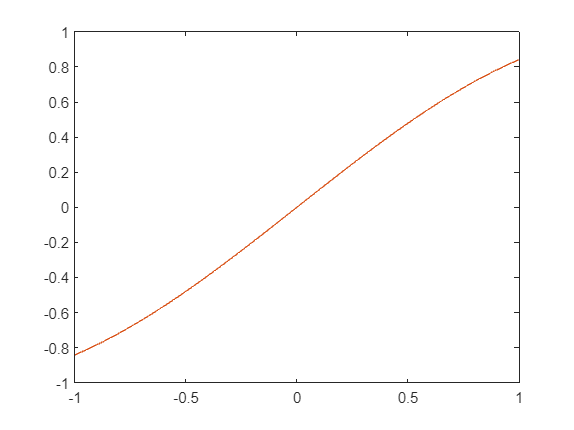


plot(x, sin(x))
hold on;
plot(x, system * p)
hold off;